# Projektowanie filtrów FIR metodą okien

% https://www.allaboutcircuits.com/uploads/articles/Table1mm.jpg

%constants 
N = 120; df = 200; fc = 300; fs = 1.2e3;
fup=fc+(df/2);   
fdown=fc-(df/2); 

% sygnal
f1 = 200; f2 = 300; f3 = 550;
t=0:1/fs:1-1/fs;
f=(0:length(t)-1)*fs/length(t);
x=sin(2*pi*f1*t)+sin(2*pi*f2*t)+sin(2*pi*f3*t); % co z cos

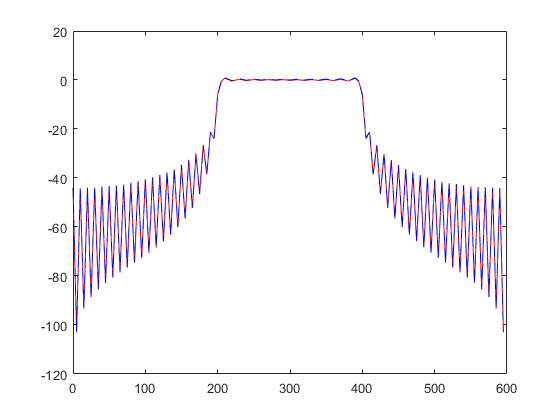

figure
[h1m f1m] = customFir(N, df, fc, fs, @boxcar);
b1 = fir1(N,[fdown/fs*2 fup/fs*2],boxcar(N+1));
[h1M,f1M] = freqz(b1,1,N,fs);
plot(f1m,20*log10(abs(h1m)), 'r')
hold on
plot(f1M,20*log10(abs(h1M)), 'b--')

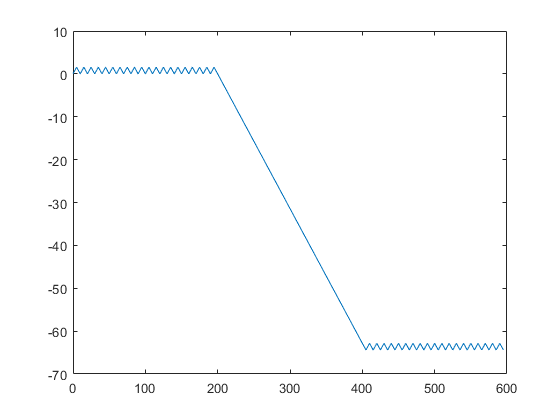


figure
plot(f1M,unwrap(angle(h1M)));

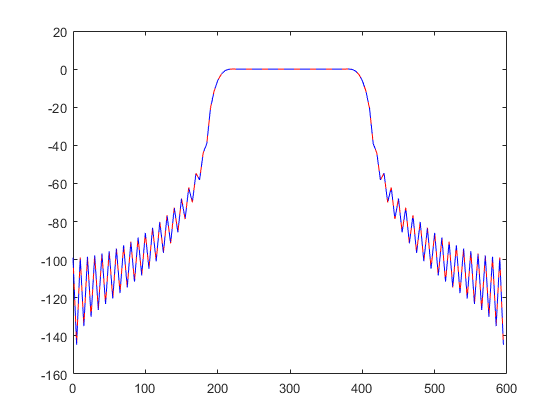

figure
[h1m f1m] = customFir(N, df, fc, fs, @hann);
b1 = fir1(N,[fdown/fs*2 fup/fs*2],hann(N+1));
[h1M,f1M] = freqz(b1,1,N,fs);
plot(f1m,20*log10(abs(h1m)), 'r')
hold on
plot(f1M,20*log10(abs(h1M)), 'b--')

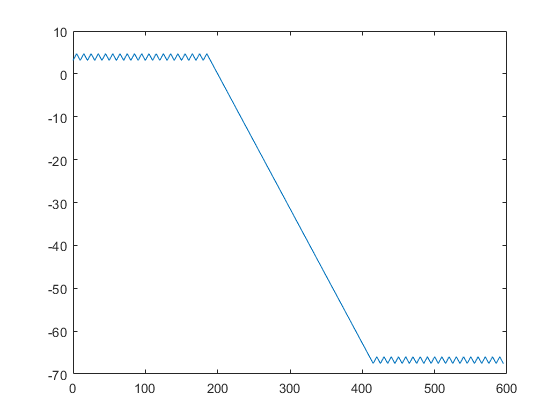


figure
plot(f1M,unwrap(angle(h1M)));

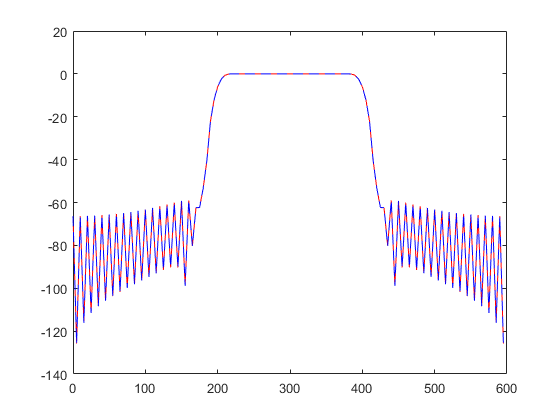

figure
[h1m f1m] = customFir(N, df, fc, fs, @hamming);
b1 = fir1(N,[fdown/fs*2 fup/fs*2],hamming(N+1));
[h1M,f1M] = freqz(b1,1,N,fs);
plot(f1m,20*log10(abs(h1m)), 'r')
hold on
plot(f1M,20*log10(abs(h1M)), 'b--')

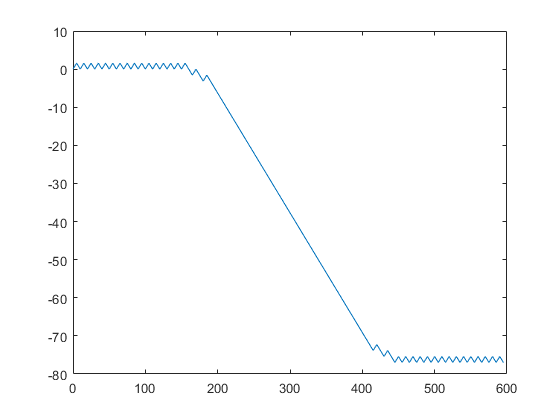


figure
plot(f1M,unwrap(angle(h1M)));

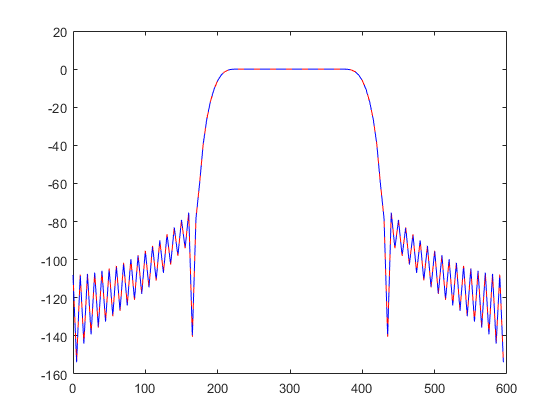

figure
[h1m f1m] = customFir(N, df, fc, fs, @blackman);
b1 = fir1(N,[fdown/fs*2 fup/fs*2],blackman(N+1));
[h1M,f1M] = freqz(b1,1,N,fs);
plot(f1m,20*log10(abs(h1m)), 'r')
hold on
plot(f1M,20*log10(abs(h1M)), 'b--')

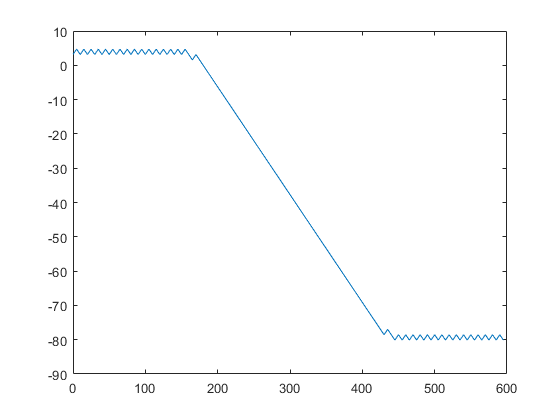


figure
plot(f1M,unwrap(angle(h1M)));

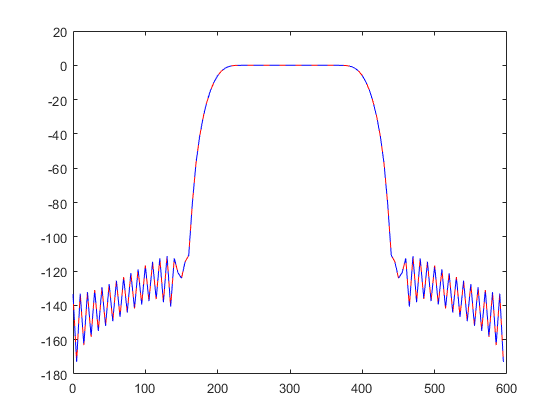

figure
[h1m f1m] = customFir(N, df, fc, fs, @blackmanharris);
b1 = fir1(N,[fdown/fs*2 fup/fs*2],blackmanharris(N+1));
[h1M,f1M] = freqz(b1,1,N,fs);
plot(f1m,20*log10(abs(h1m)), 'r')
hold on
plot(f1M,20*log10(abs(h1M)), 'b--')

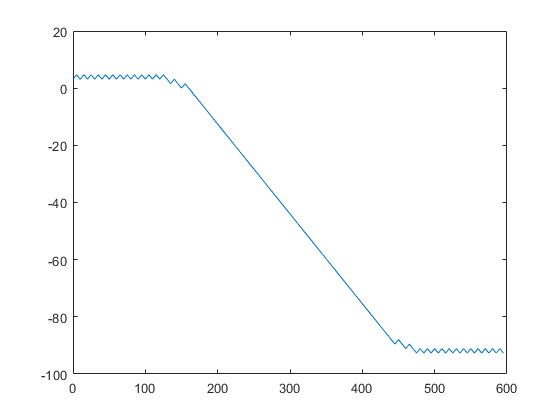


figure
plot(f1M,unwrap(angle(h1M)));

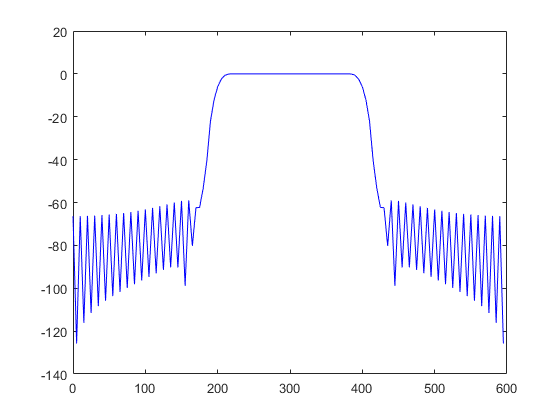

% custom plot 
figure
plot(f1M,20*log10(abs(h1M)), 'b')

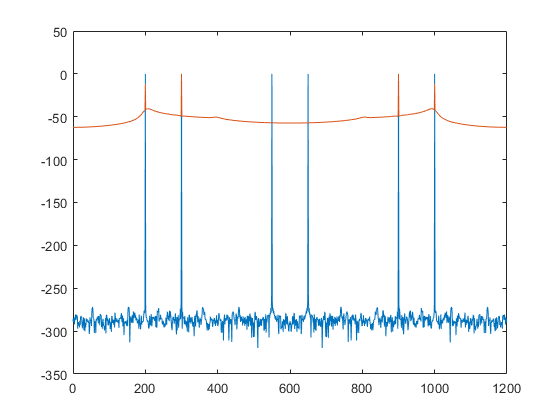


%figure
%plot(t, x);
%hold on
%plot(t,filtfilt(b1, 1, x));
%xlim([0 0.02])

figure
plot(f,20*log10(abs(fft(x)/length(t)*2)));
hold on
plot(f,20*log10(abs(fft(filtfilt(b1, 1, x))/length(t)*2)));


$$\Delta \omega =2\pi \frac{\Delta f}{f_{\mathrm{samp}} }$$


function h = myfir(M)
    %M =(N-1)/2;
    nvec = 0:M;
    h = hamming(M+1)'.*(0.5*sinc((nvec-20)/2));
    
    plot((0.5*sinc((nvec-20)/2)))
end

function [H F] = customFir(M, dr, fc, fs, func)
    
    n = 0:M;

    % hertz to rad and start, stop rad freq
    wleft   = 2*pi*(fc-dr/2)/fs;
    wright  = 2*pi*(fc+dr/2)/fs;
    %wcenter = 2*pi*fc/fs;
    wcenter = M/2;
    
    % substr of two lowpass filters with time shift:
    hd = (wright/pi)*sinc(wright*(n-wcenter)/pi) - (wleft/pi)*sinc(wleft*(n-wcenter)/pi);
    
    %plot(1:M+1,hd)
    
    h = func(M+1)'.*hd;
    
    [H F] = freqz(h,1,M,fs);
end

function [h, a] = fir_mse(N,Omc)
    M =(N-1)/2;
    
    dOm = pi/1e3;
    
    h3 = [-1 0 1];
    
    Om = -pi : dOm : pi-dOm;
    
    NOm  = length(Om);
    iR = zeros(M+1, M+1);
    
    iR(1,1) = 1;
    
    for k=2:M+1
        iR(k,k) = 2;
    end
    
    OmD = ones(size(Om));
    
    ind = find(abs(Om)>Omc);
    
    OmD(ind) = 0;
    
    c = zeros(M+1,1);
    
    for k=0:M
        c(k+1,1)=sum(OmD.*cos(k*Om))/NOm;
    end
    
    a=iR*c;
    
    for k=1:M
        h(k) = a(k+1)/2;
    end
    
    h = [fliplr(h), a(1), h];
    
    
    
%h = fir_mse(129, 1.5);
%[h1 f1] = freqz(h,1,129,1.2e3);
%plot(f1,20*log10(abs(h1)))
%
end
